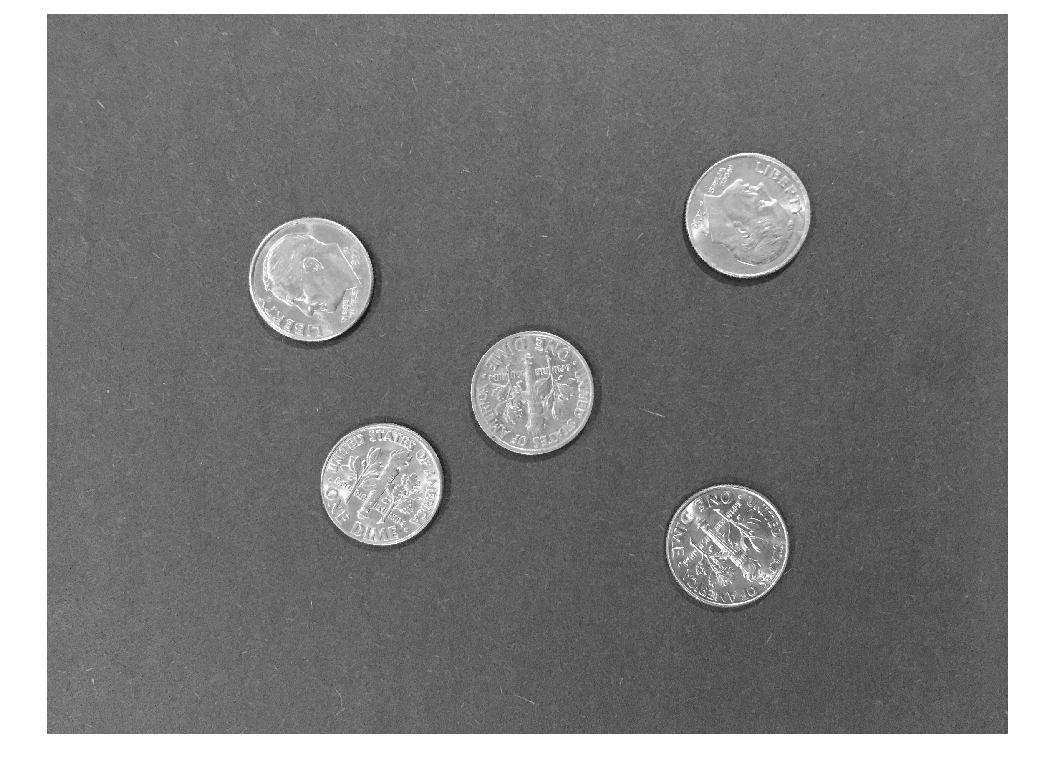

img = imread("dimes3.jpg");
imshow(img)

[threshold, efficacy] = graythresh(img)

threshold = 0.5608

efficacy = 0.6967

threshold255 = threshold * 255

threshold255 = 143

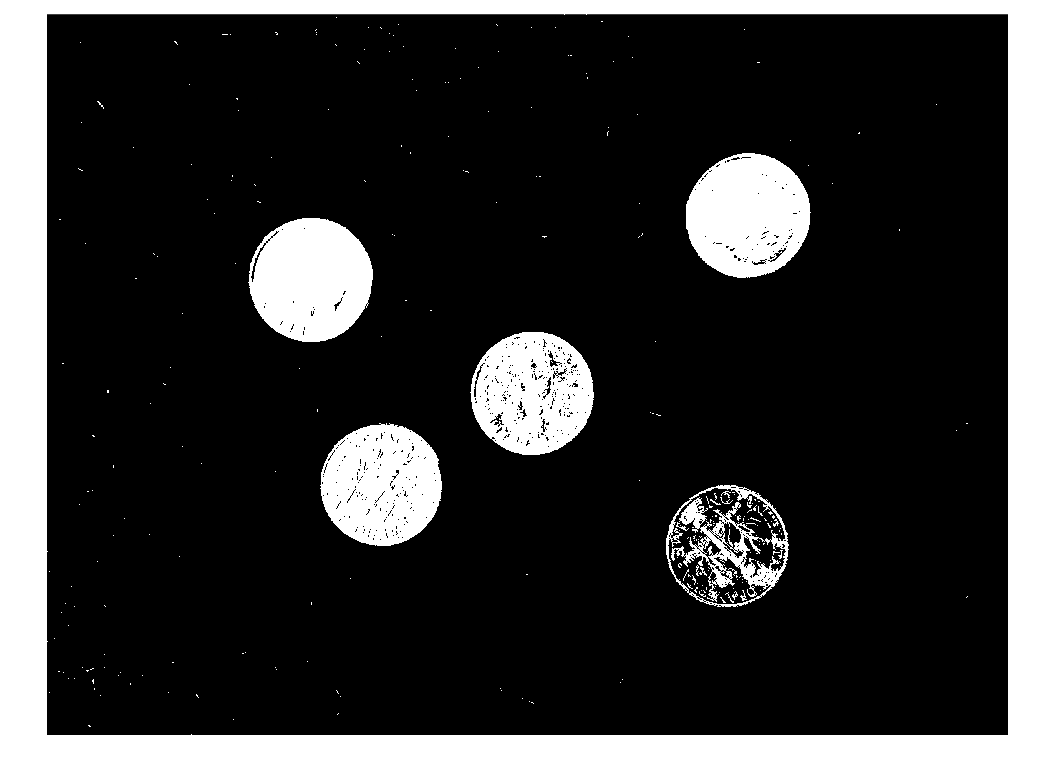

imthresh = imbinarize(im2gray(img), threshold);
imshow(imthresh)

nnz(imthresh)

ans = 594617

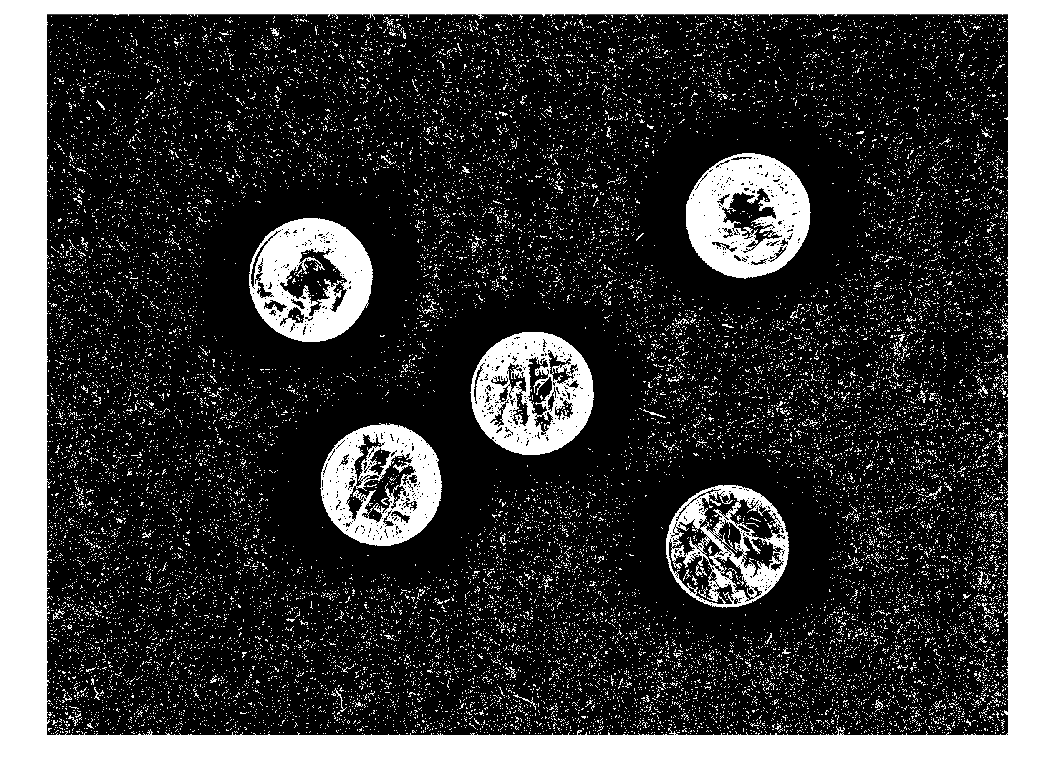

imgadaptive = imbinarize(im2gray(img), "adaptive", "ForegroundPolarity", "bright", ...
    "Sensitivity",0.5);

imshow(imgadaptive)

img = imread("blueberries.jpg");

img = 744×650×3 uint8 array
img(:,:,1) =

   169    89    42    29    42    96   131   183   200   195   185   155   159   190   190   188   194   174   128   123   148   139   175   195   216   230   217   189   179   140   116    96    93    75    53    57    93   110   115   127   126   113    61    51    79   110   129   157   173   179   184   178   144   100   101   139   168   159   165   153   163   207   216   195   181   186   194   172   134   126   135   132   129   125   121   130   130   127   136   144   149   139   135   140   145   140   137   136   151   166   180   188   199   211   206   191   160   146   171   183   167   157   143   135   164   200   208   197   190   184   175   148   157   164   128   113   104    96    93    99    81   119   117    88    85    81    75    81    82    84    86    84    77    66    59    58    48    52    51    47    48    50    45    35    41    55    51    49    45    51    47    55    63    72    80    87    95    96   108   1

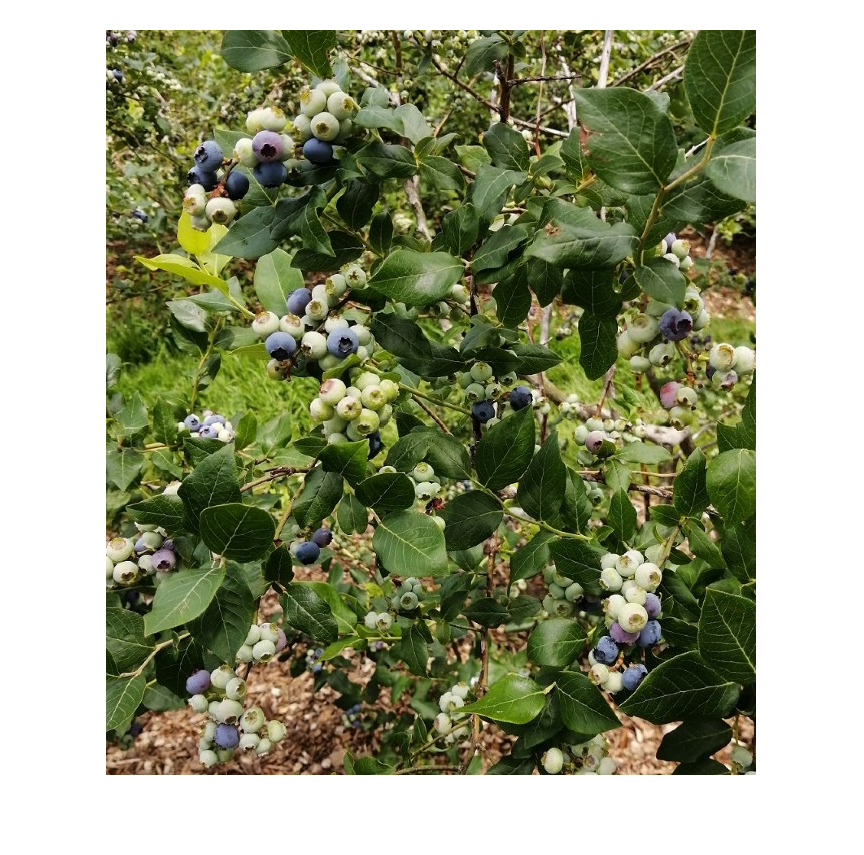

imshow(img)

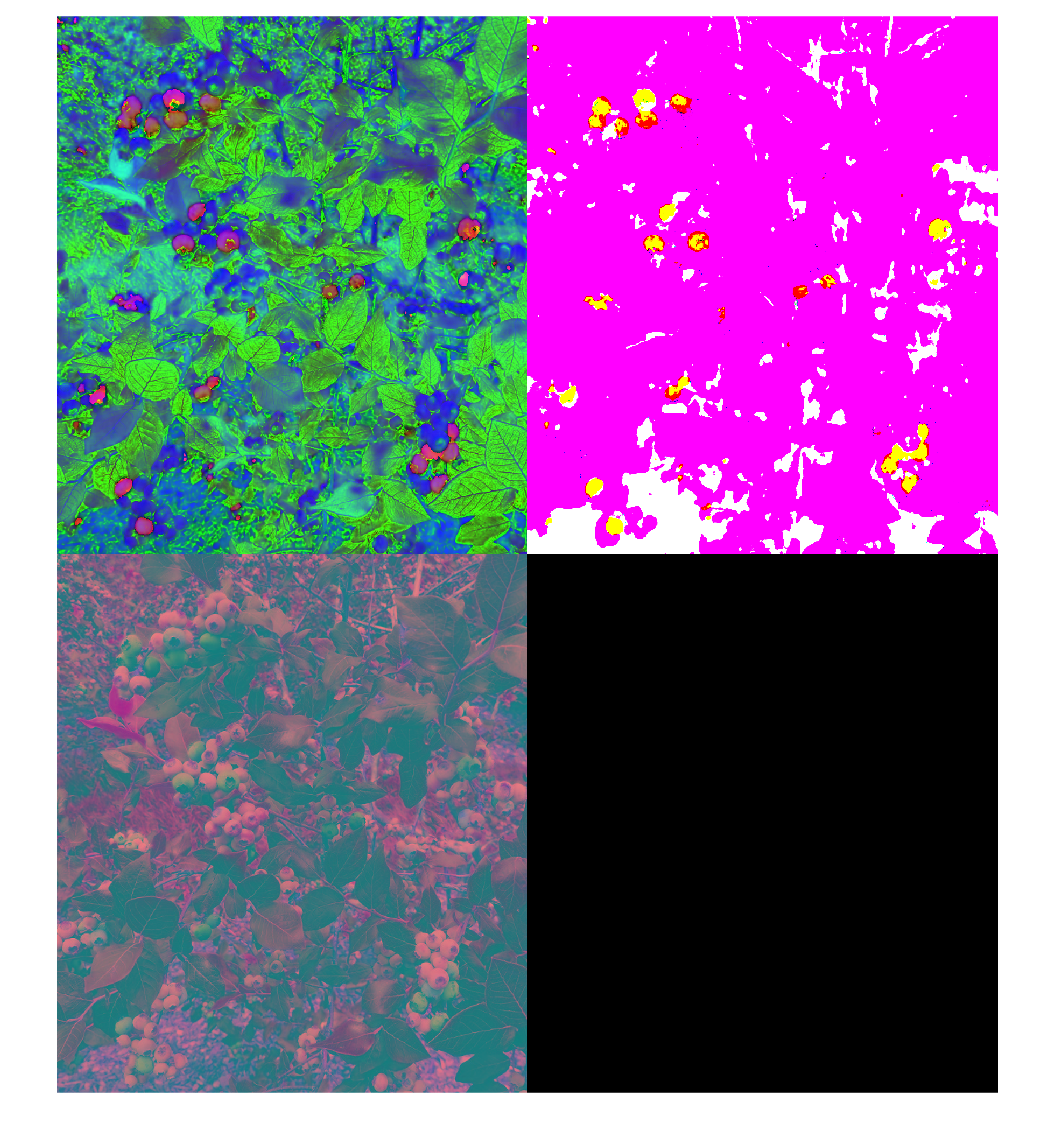

hsv = rgb2hsv(img);
lab = rgb2lab(img);
ycb = rgb2ycbcr(img);


montage({hsv, lab, ycb})